clc
clear

**NOTE:** This document contains transfer functions and data for the motors when coupled together with the mechanical system.

DO NOT change variable naming or values since other documents are also dependent on them!

## INIT of PD-controller info

% PD-controller gains
Kp = 1 %5 %25;

Kp = 1

Ki = 0;
Kd = 0 %0.001 %0.1;

Kd = 0


Ts = 1/200; % Sampling time
N = 1000;   % Filter order

## Transfer function setup

s = tf('s');

% Defining variables for transfer function
k_tilt_avg  = 1.73;     % DC-gain rps/V (rounds per second / Volts)
k_pan_avg   = 1.84;     % DC-gain rps/V (rounds per second / Volts)
tau_tilt    = 0.00575;   % Time constant (63.2%)
tau_pan     = 0.00591;   % Time constant (63.2%)

% Transfer functions
Gs_tilt = k_tilt_avg / ( (tau_tilt*s + 1) * s );
Gs_pan  = k_pan_avg  / ( (tau_pan*s  + 1) * s  );

% Extracting numerator and denominator from pan/tilt transfer functions
[Num_tilt, Den_tilt] = tfdata(Gs_tilt, 'v');
[Num_pan,  Den_pan]  = tfdata(Gs_pan,  'v');

%%% Creating Closed Loop system with PDF-controller %%%
PDF = Kp + Ki * (1/s) + Kd * ( N/(1 + N * (1/s)) ); % PDF-controller
CL_pan = feedback(PDF*Gs_pan,1);    % Pan closed loop
CL_tilt = feedback(PDF*Gs_tilt,1);  % Tilt closed loop

% Calculating pan/tilt closed loop systems bandwidths 
CL_pan_bandwidth = bandwidth(CL_pan)    % Pan closed loop bandwidth

CL_pan_bandwidth = 1.8558

CL_tilt_bandwidth = bandwidth(CL_tilt)  % Tilt closed loop bandwidth

CL_tilt_bandwidth = 1.7432

## Pan/tilt closed loop system step responses

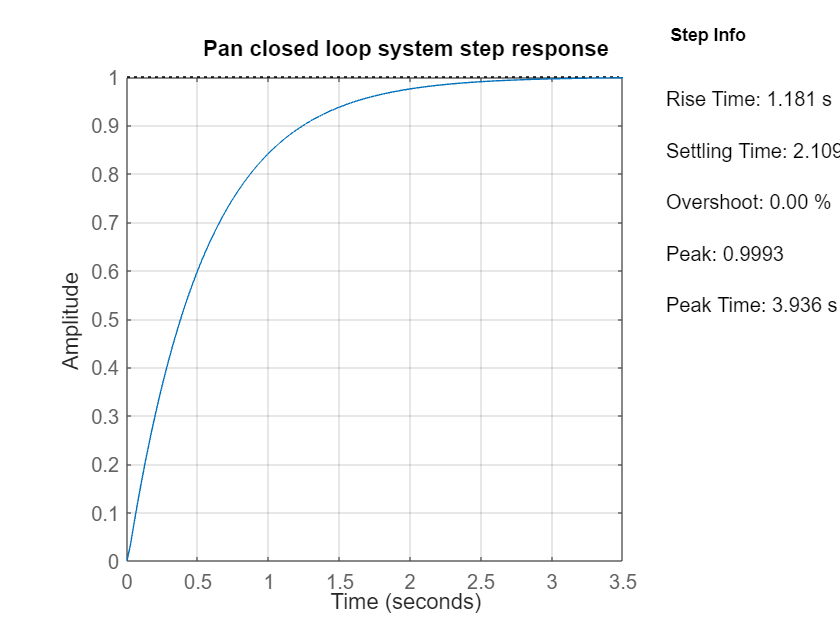

%%% PAN CLOSED LOOP STEP RESPONSE %%%
figure;
hold on
% Left: Step response
subplot(1,5,[1 2 3 4]);
step(CL_pan);
grid on;
title('Pan closed loop system step response');
% Right: Step info text
info_pan = stepinfo(CL_pan);
subplot(1,5,5);
axis off; % Hide axes
text(0.1, 0.9, sprintf('Rise Time: %.3f s', info_pan.RiseTime));
text(0.1, 0.8, sprintf('Settling Time: %.3f s', info_pan.SettlingTime));
text(0.1, 0.7, sprintf('Overshoot: %.2f %%', info_pan.Overshoot));
text(0.1, 0.6, sprintf('Peak: %.4f', info_pan.Peak));
text(0.1, 0.5, sprintf('Peak Time: %.3f s', info_pan.PeakTime));
title('Step Info');
hold off

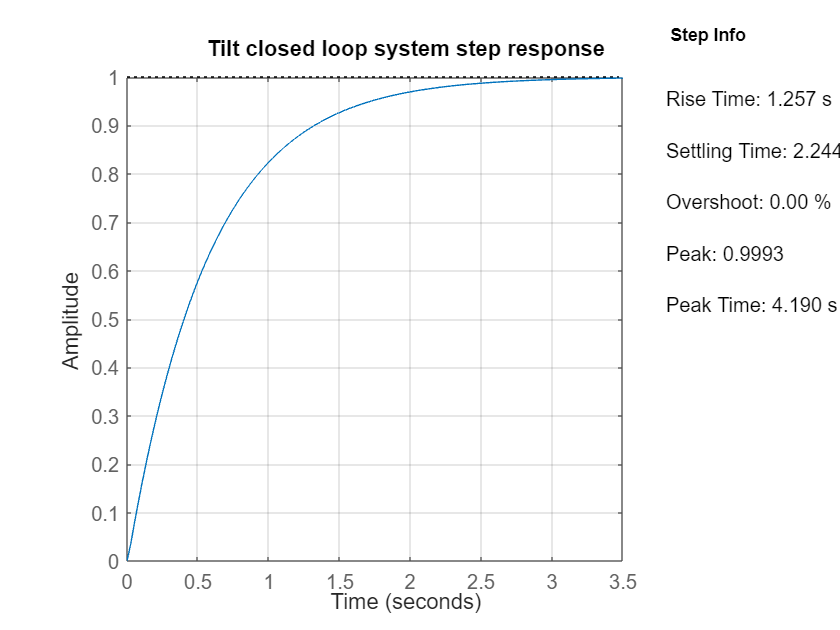

%%% PAN CLOSED LOOP STEP RESPONSE %%%
figure;
hold on
% Left: Step response
subplot(1,5,[1 2 3 4]);
step(CL_tilt);
grid on;
title('Tilt closed loop system step response');
% Right: Step info text
info_tilt = stepinfo(CL_tilt);
subplot(1,5,5);
axis off; % Hide axes
text(0.1, 0.9, sprintf('Rise Time: %.3f s', info_tilt.RiseTime));
text(0.1, 0.8, sprintf('Settling Time: %.3f s', info_tilt.SettlingTime));
text(0.1, 0.7, sprintf('Overshoot: %.2f %%', info_tilt.Overshoot));
text(0.1, 0.6, sprintf('Peak: %.4f', info_tilt.Peak));
text(0.1, 0.5, sprintf('Peak Time: %.3f s', info_tilt.PeakTime));
title('Step Info');
hold off

## Plotting Bode diagrams for pan/tilt transfer functions

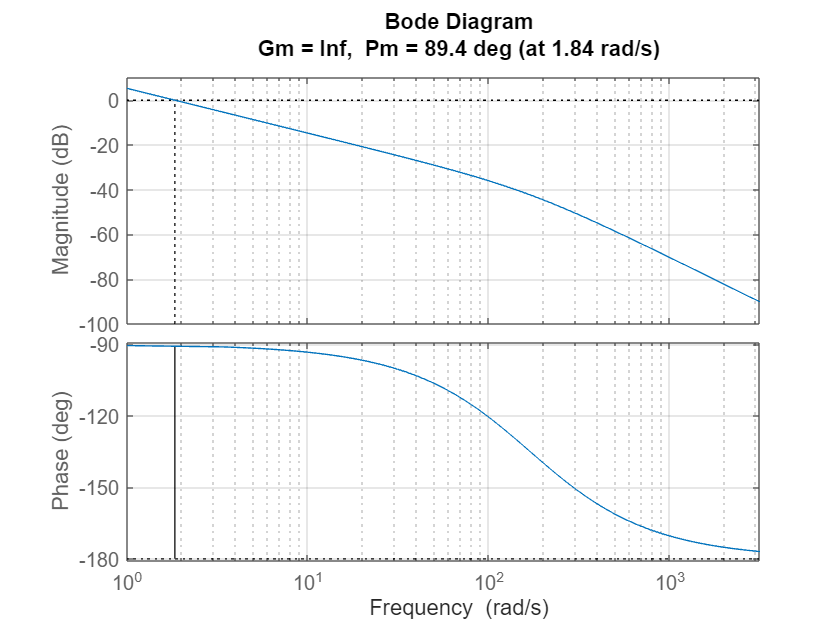

%%% Pan transfer function Bode Diagram %%%
figure;
hold on
margin(Gs_pan, {0, 10^(3.5)}), grid on

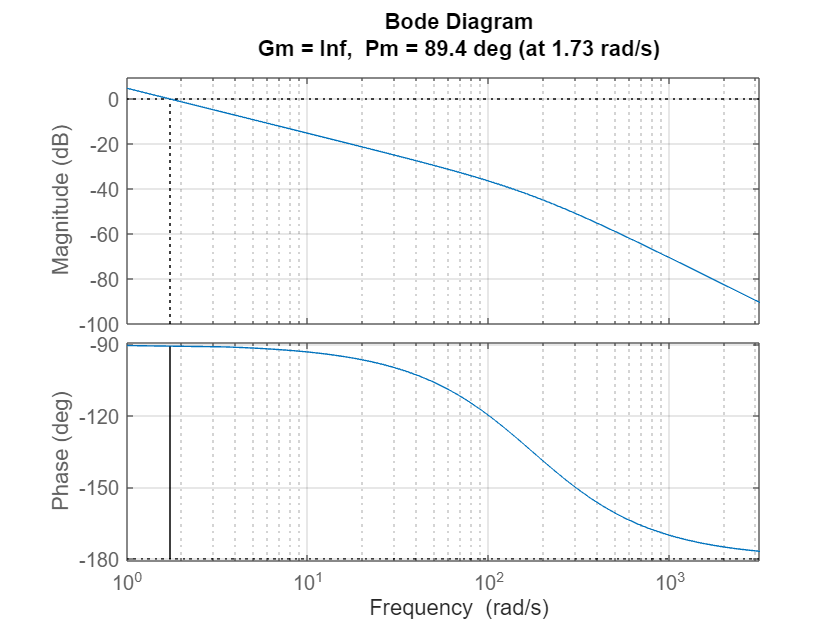

%%% Tilt transfer function Bode Diagram %%%
figure;
hold on
margin(Gs_tilt, {0, 10^(3.5)}), grid on

## Plotting Bode diagrams with margins for pan/tilt closed loops systems

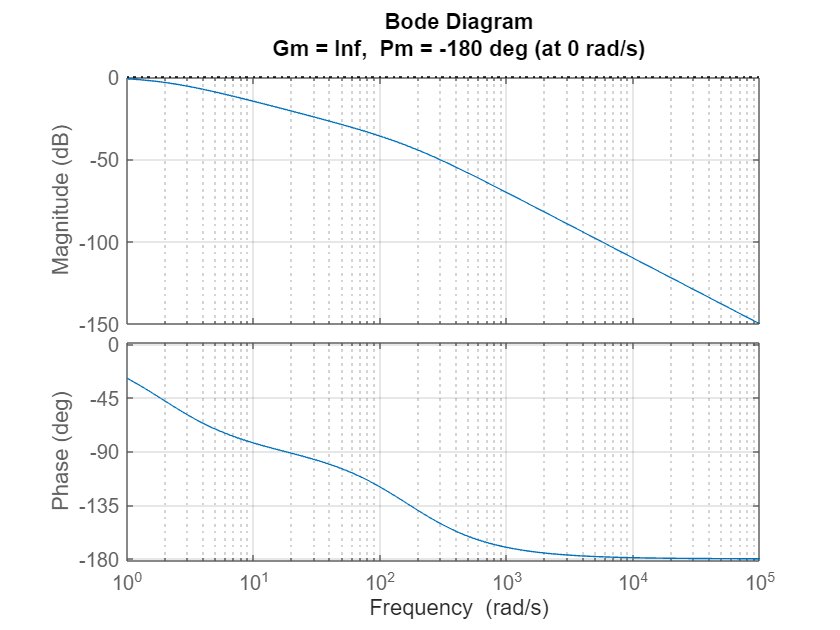

%%% Pan closed loop system Bode Diagram with margins %%%
figure;
hold on
margin(CL_pan, {1, 1e5}), grid on

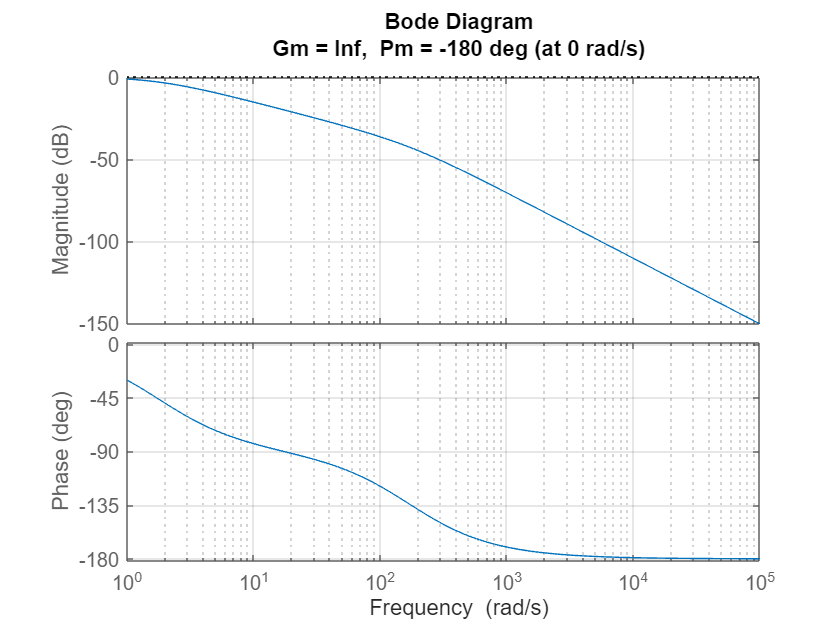

%%% Tilt closed loop system Bode Diagram with margins %%%
figure
margin(CL_tilt, {1, 1e5}), grid on
hold off

## Nyquist plot with plot handle

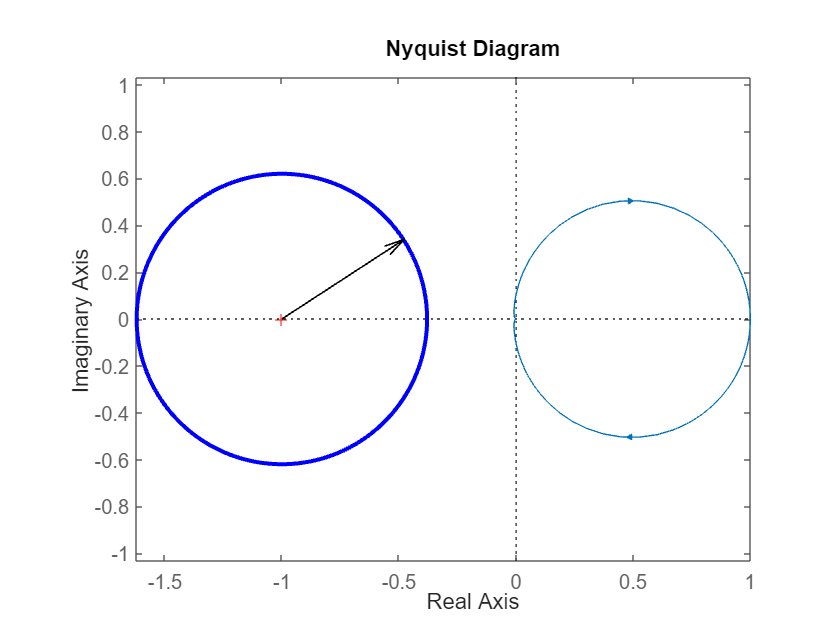

figure
hold on
r = 0.62;               % radius
x0 = -1; y0 = 0;      % center of circle

theta = linspace(0, 2*pi, 200);  % angles
x = x0 + r * cos(theta);
y = y0 + r * sin(theta);

plot(x, y, 'b-', 'LineWidth', 2)
axis equal
grid on
title('Circle with radius 1 centered at (0,0)')
nq_CL_pan = nyquistplot(CL_pan);

% Draw arrow
x_start = -1;
y_start = 0;
dx = -0.4776 - x_start;
dy = 0.34 - y_start;
quiver(x_start, y_start, dx, dy, 0,'MaxHeadSize', 0.5, 'Color', 'black', 'LineWidth', 0.8);

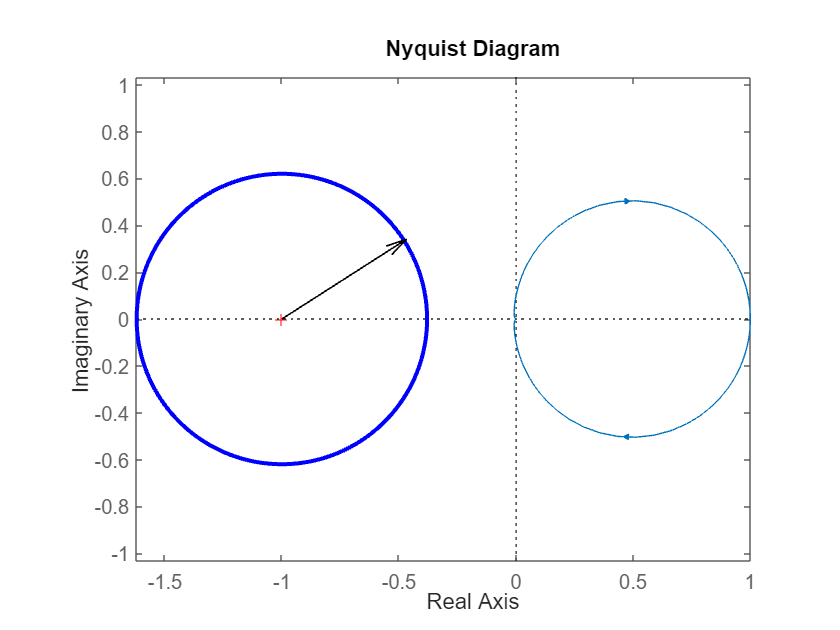


% Create a Nyquist plot with plot handle
figure
hold on
r = 0.62;               % radius
x0 = -1; y0 = 0;      % center of circle

theta = linspace(0, 2*pi, 200);  % angles
x = x0 + r * cos(theta);
y = y0 + r * sin(theta);

plot(x, y, 'b-', 'LineWidth', 2)
axis equal
grid on
title('Circle with radius 1 centered at (0,0)')
nq_CL_tilt = nyquistplot(CL_tilt);

% Draw arrow
x_start = -1;
y_start = 0;
dx = -0.469 - x_start;
dy = 0.34 - y_start;
quiver(x_start, y_start, dx, dy, 0,'MaxHeadSize', 0.5, 'Color', 'black', 'LineWidth', 0.8);

hold off

## Root locus plot

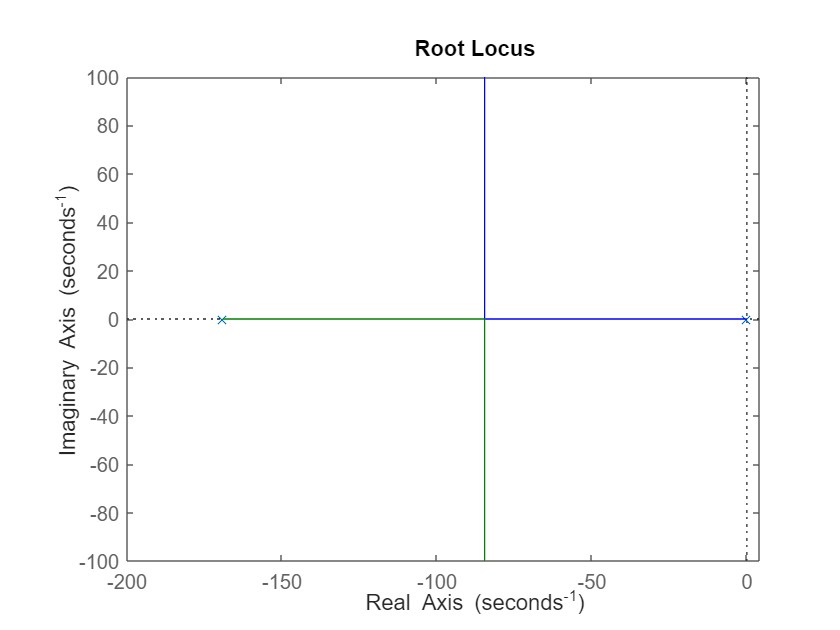

K = 1;
rlocus(Gs_pan*K);

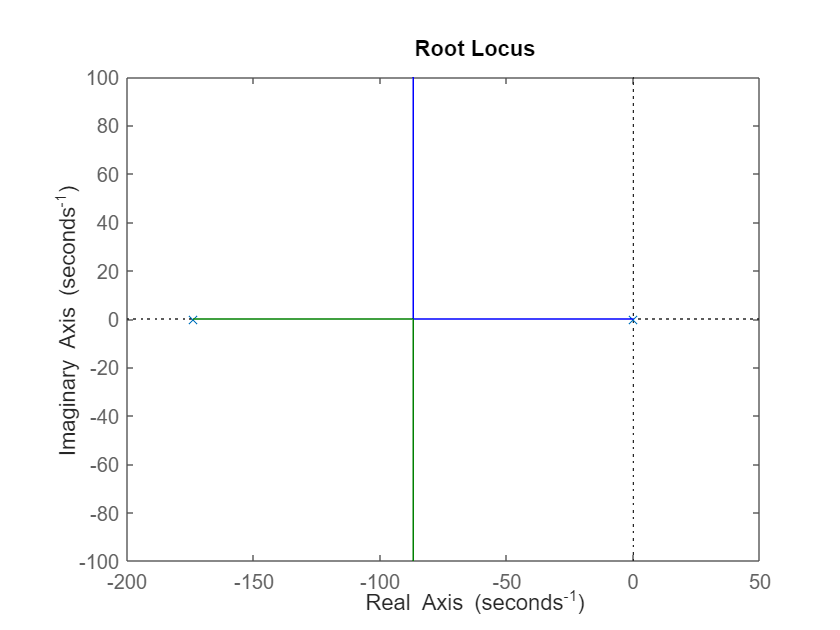

rlocus(Gs_tilt*K);